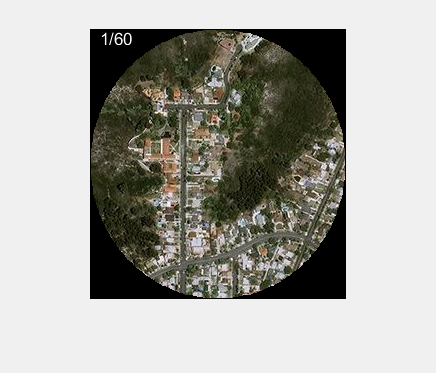

clc
clear all
close all

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%  Get images  %%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);

counter=1;
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   if currentfilename(1)==letter
       currentimage = imread(directory+currentfilename);
       images{counter} = currentimage;
       [~,imageNames{counter},~] = fileparts(currentfilename);
       counter=counter+1;
   end
end

% Randomize image order
neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%  Important params  %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fig = figure;
set(gcf,'Visible','on'); % Open figure window
stitched = zeros(length(images),1); % Logical: images stitched
stitched(1)=1;
out = images{1}; % Set first image as output
outcount = 1; % Count number of additional output images
length_images = length(images);
c_thresh = 0.01; % Confidence threshold
c_speedthresh = 0.01; % Speed confidence threshold
c_speedthresh_trip=false; % Speed threshold triggered
v_thresh = 1.5; % Overlap threshold
points = 0.5; % Scale factor for number of considered points

plot_anim(out,stitched);


while true
    % Reset local variables
    confidences = zeros(length(stitched),4);
    c_speedthresh_trip=false;
    for i=1:length(stitched)
        % If an image is unstitched, try to stitch it
        if stitched(i)==0
            [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, points, true);
            confidences(i,:)=[final_confidence,final_delta_x,final_delta_y, i];
            % If confidence exceeds the speed threshold, try to stitch
            if confidences(i,1)>=c_speedthresh
                [out, valid, nd] = merge_images(out, images{i}, round(-confidences(i,2)), round(-confidences(i,3)),v_thresh/1.5, true);
                if valid
                    disp("Confidence: "+confidences(i,1))
                    disp("Norm Diff: "+nd)
                    c_speedthresh_trip=true;
                    stitched(i)=1;
                    plot_anim(out,stitched);
                end
            end
        end
    end
    % If no valid stitch has already occurred, try with descending
    % confidence
    if ~c_speedthresh_trip
        confidences = sortrows(confidences,1,"descend");
        valid = false;
        for c=1:size(confidences,1)
            % Try confidences that meet the minimum threshold
            if confidences(c,1)>=c_thresh
                [out, valid, nd] = merge_images(out, images{confidences(c,4)}, round(-confidences(c,2)), round(-confidences(c,3)),v_thresh, true);
                if valid
                    disp("Confidence: "+confidences(c,1))
                    disp("Norm Diff: "+nd)
                    stitched(confidences(c,4))=1;
                    plot_anim(out,stitched);
                    break
                end
            end
        end
        % If no stitches were found, make adjustments
        if ~valid
            stitched = [stitched;0];
            % If all images attempted, adjust parameters
            if all(stitched(1:length_images))
                c_thresh = c_thresh/1.5 % relax confidence
                v_thresh = v_thresh+0.75 % relax overlap
                points = min(3,points+0.5) % increase stringency
                
                % Strip extra elements
                stitched = stitched(length_images+1:end);
                images = images(length_images+1:end);
                length_images = length(stitched);
            end
            % Save current image into next slot
            images{length(images)+1} = out;
            idx = find(stitched==0,1,"first");
            % Load next unstitched image
            out = images{idx};
            stitched(idx)=1;
            plot_anim(out,stitched);
        end
    end
    % If all stitched or stuck, exit
    if all(stitched) | v_thresh>12
        break
    end
end

Confidence: 0.019324


    "Norm Diff: 0.88285"
    "Norm Diff: 0.88115"
    "Norm Diff: 0.9129"



Confidence: 0.024877


    "Norm Diff: 0.73304"
    "Norm Diff: 0.73085"
    "Norm Diff: 0.74164"



sum(stitched)
plot_anim(out,stitched);
text(10,40,"Done!","Color",[1,1,1]);
imwrite(out, "Output/"+letter+"/"+rand()+".png");